# Assignment1-1 Segway

Members:

1,Zhu Chenhao 22320630

2,Liuange 22320627

3,Chen Dongren 22320616

4,YUANJIA 22320617

5,Bie Zhi 22320615

6,Zhang Miaote 22320618

7,Zhang Yichong 22320631

8,Xiong Zhuoen 22320633

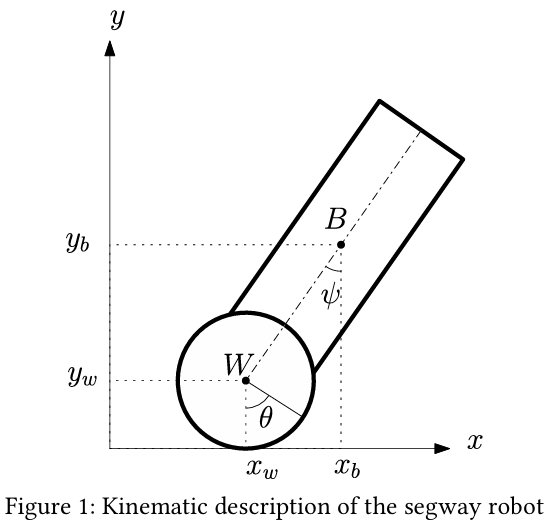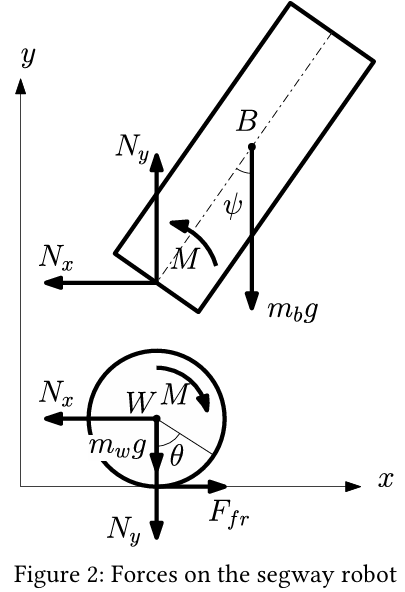

# Calculations:

r = 0.025;
l = 0.12;
m_b = 0.5;
m_w = 0.01;
J_b = 0.0072;
J_w = 1e-4;
g = 9.81;

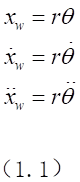     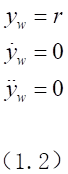     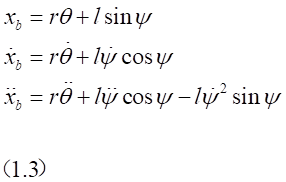    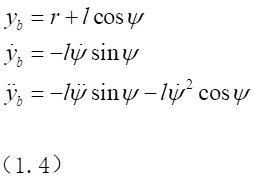

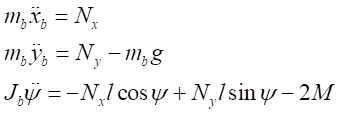

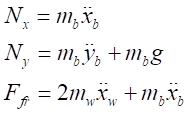

`, `

`, `

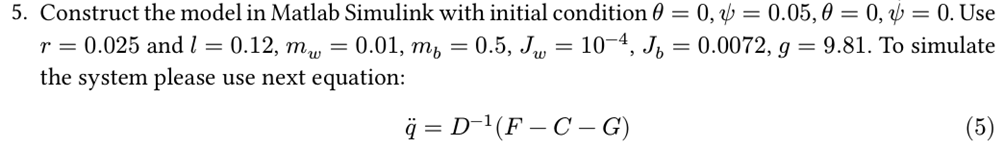

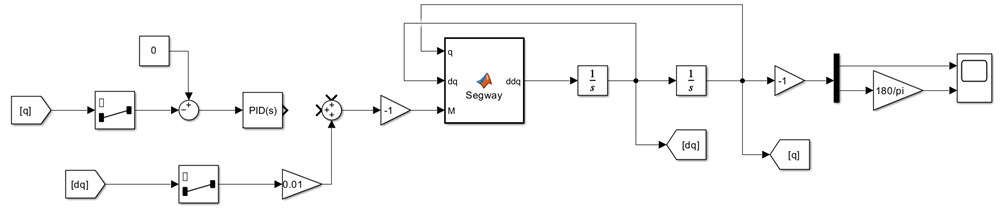

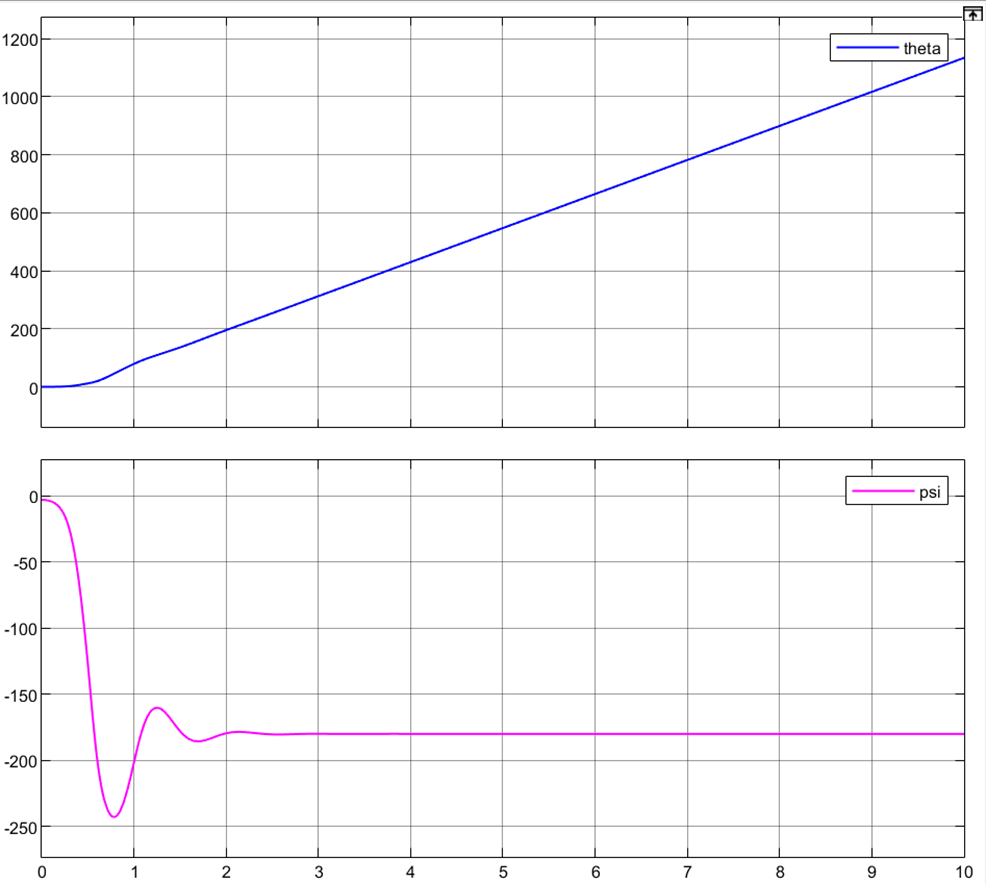

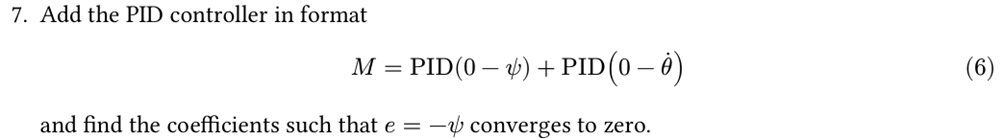

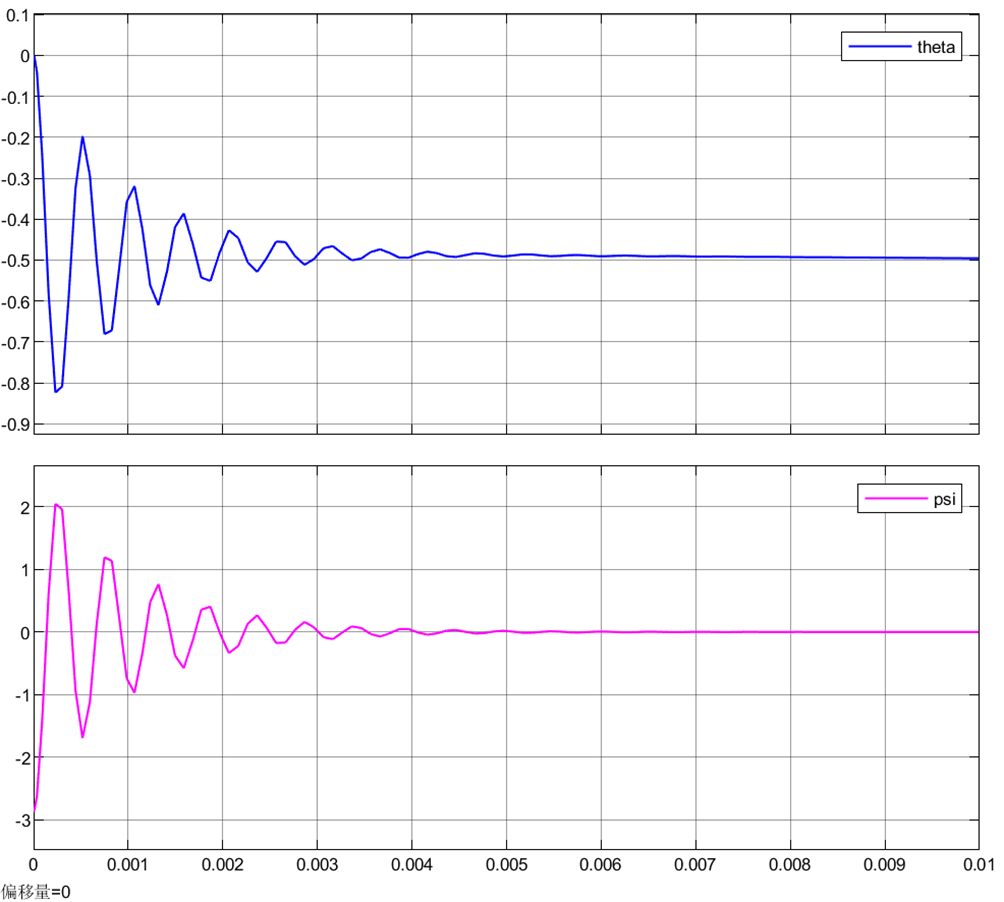

syms theta psi dtheta dpsi ddtheta ddpsi M real

函数或变量 'eq1' 无法识别。


% Wheel
x_w = r * theta;
dx_w = r * dtheta;
ddx_w = r * ddtheta;

y_w = r;
dy_w = 0;
ddy_w = 0;

% Body
x_b = r*theta + l*sin(psi);
dx_b = r*dtheta + l*dpsi*cos(psi);
ddx_b = r*ddtheta + l*ddpsi*cos(psi) - l*dpsi^2*sin(psi);

y_b = r + l*cos(psi);
dy_b = -l*dpsi*sin(psi);
ddy_b = -l*ddpsi*sin(psi) - l*dpsi^2*cos(psi);


% syms N_x N_y F_fr real
% 
% % Body
% eq1 = m_b * ddx_b == N_x;
% eq2 = m_b * ddy_b == N_y - m_b*g;
% eq3 = J_b * ddpsi == -N_x*l*cos(psi) + N_y*l*sin(psi);
% 
% % Wheel
% eq4 = 2*m_w * ddx_w == -N_x + F_fr;
% % eq5 = m_w * ddy_w == N_y - m_w*g;
% eq6 = 2*J_w * ddtheta == 2*M - F_fr*r;

% equations = [eq1; eq2; eq3; eq4; eq5; eq6];
% vars = [N_x, N_y, F_fr, ddtheta, ddpsi];
% sol = solve(equations, vars);
% 
% ddtheta_eq = simplify(sol.ddtheta);
% ddpsi_eq = simplify(sol.ddpsi);
% f = [dtheta;
%      dpsi;
%      ddtheta_eq;
%      ddpsi_eq];
% 
% matlabFunction(f, 'File', 'segway_dynamics', ...
%                'Vars', {'theta', 'psi', 'dtheta', 'dpsi', 'M'});